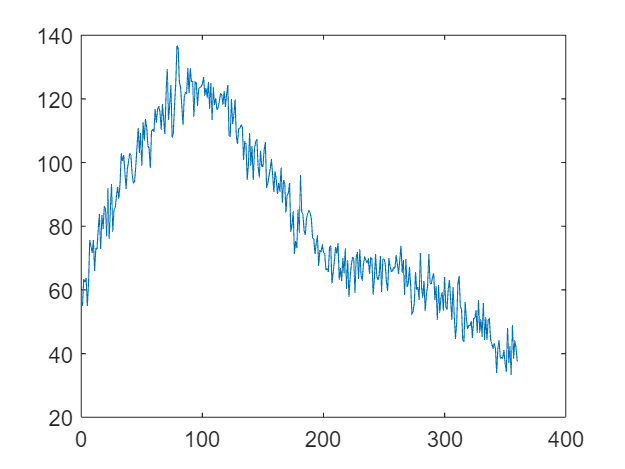

for i = 1:360
    data(i) = simulated_response_value(i).data;
end

plot(data)

lik = bayes_grid_function(data).lik;
lik = lik/sum(lik,'all');
[M,I] = max(lik,[],'all'); % get maximum liklihood of parameters value and get the index of parameters
[i,j,k,h] = ind2sub(size(lik),I);


p_rp = sum(sum(sum(lik,4),3),2);
p_rp = p_rp/sum(p_rp);
p_ang = sum(sum(sum(lik,4),3),1);
p_ang = p_ang/sum(p_ang);
p_rn = squeeze(sum(sum(sum(lik,4),2),1)); 
p_rn = p_rn/sum(p_rn);
p_sig = squeeze(sum(sum(sum(lik,3),2),1));
p_sig = p_sig/sum(p_sig);

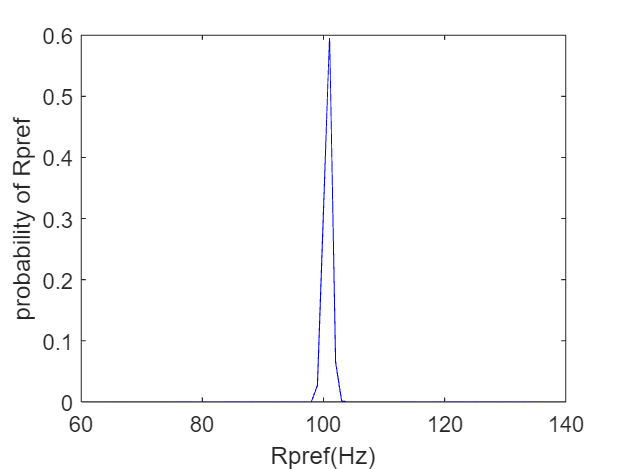

plot(65:135,p_rp,'b'),
xlabel("Rpref(Hz)"), 
ylabel("probability of Rpref"),

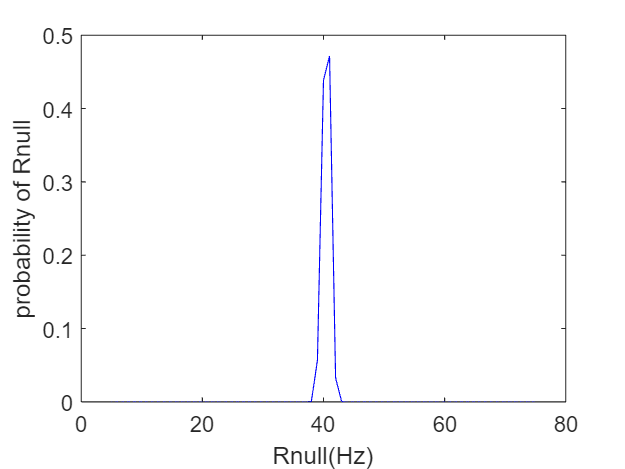


plot(5:75,p_rn,'b'),
xlabel("Rnull(Hz)"),
ylabel("probability of Rnull"),

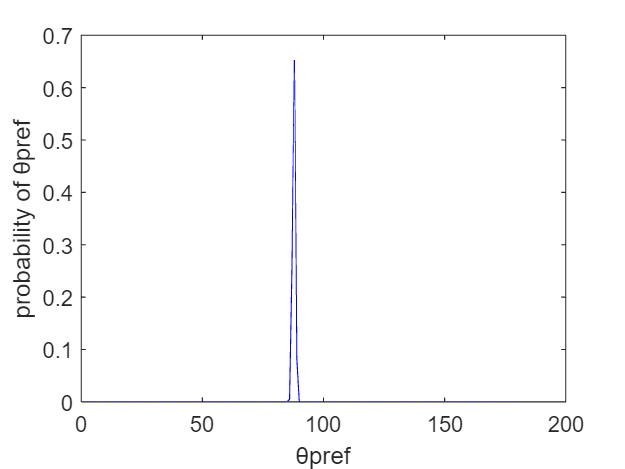


plot(1:180,p_ang,'b'),
xlabel("θpref"),
ylabel("probability of θpref"),

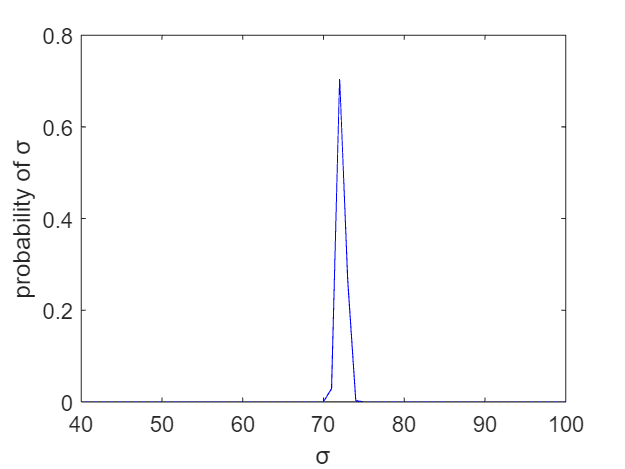


plot(40:100,p_sig,'b'),
xlabel("σ"),
ylabel("probability of σ"),